# Pizza3 - WORKSHOP - PostTreatment - Part 2

INRAE\Han Chen, Olivier Vitrac - rev. 2023-08-28, 2023-09-06

## Synopsis

The second part of the worshop will demonstrate how to interpret simulated data in space by projecting them on stuctured or unstructured grids, and to extract stresses.

The visualization techniques and use of the Verlet list are more sophisticated than in part 1. Computations are more expensive and require understanding of vectorial algebra.

The approaches are illustrated on more realistic data.

## Description and dependencies

%% Workshop Main File - Part 2
% This script demonstrates the data preprocessing, analysis, and visualization techniques 
% using 'lamdumpread2', a custom function for reading LAMMPS dump files.

% File Structure (change your local path to reflect the content)
% ├── example2.m (main developing file)
% ├── notebook
% │  ├── example2.mlx <-- this file
% └── ...
% └── data folder (dumps/pub1/)

%INRAE\Olivier Vitrac, Han Chen (rev. 2023-08-30,2023-08-31)

% Revision history
% 2023-09-04,05 implement grid interpolation
% 2023-09-06 deploy as a notebook


## 1. Initialization

### 1.1 General definitions

%% Initialization and Preprocessing 
% -------------------------------------------------
% Turn preprocessing on or off based on `PREPROCESS_FLAG`. 
% 'lamdumpread2' splits large 3D dump files if the flag is true.

statvec = @(f,before,after) dispf('%s: %s%d values | average = %0.5g %s', before, ...
    cell2mat(cellfun(@(x) sprintf(' %0.1f%%> %10.4g | ', x, prctile(f, x)), {2.5, 25, 50, 75, 97.5}, 'UniformOutput', false)), ...
    length(f), mean(f),after); % user function to display statistics on vectors (usage:  statvec(f,'myvar','ok'))

PREPROCESS_FLAG = false;
addpath(rootdir(pwd),'-begin')
if PREPROCESS_FLAG
    datafolder = '../dumps/pub1/';
    lamdumpread2(fullfile(datafolder,'dump.*'),'split'); % for large 3D
end

%% File-specific Processing (same file as in Example1.m but larger)
% -----------------------------------------------------------------
% A specific dump file is selected and pre-processed to extract data and 
% save to default folders for further operations.
datafolder = '../dumps/pub1/';
dumpfile = 'dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle';
datafolder = lamdumpread2(fullfile(datafolder,dumpfile),'search'); % fix datafolder based on initial guess1.2 

Look for 'dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle'... (be patient)
...found in '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary'

The dumpfile 'dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle' has been found with the method 'splitfolder'
	in the folder: ../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary
the original search started in ../dumps/pub1
The frame (split) folder is: ../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
The first frame (split) is located in: ../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle/TIMESTEP_000000000.mat
The prefetch is split in several files.
1014 TIMESTEPS are availble:
  Column 01	  Column 02	  Column 03	  Column 04	  Colum

### 1.2 Typical frame

defaultfiles = lamdumpread2(fullfile(datafolder,dumpfile),'default'); % default folder (just for check)

%% Data Extraction
% -------------------------------------------------
% Extract the types of atoms and the list of available frames
X0 = lamdumpread2(fullfile(datafolder,dumpfile)); % default frame

The prefetch is split in several files.
1014 TIMESTEPS are availble:
  Column 01	  Column 02	  Column 03	  Column 04	  Column 05	  Column 06	  Column 07	  Column 08	  Column 09	  Column 10	
        0	   102000	   204000	   306000	   408000	   510000	   612000	   714000	   816000	   918000	
     1000	   103000	   205000	   307000	   409000	   511000	   613000	   715000	   817000	   919000	
     2000	   104000	   206000	   308000	   410000	   512000	   614000	   716000	   818000	   920000	
     3000	   105000	   207000	   309000	   411000	   513000	   615000	   717000	   819000	   921000	
     4000	   106000	   208000	   310000	   412000	   514000	   616000	   718000	   820000	   922000	
     5000	   107000	   209000	   311000	   413000	   515000	   617000	   719000	   821000	   923000	
     6000	   108000	   210000	   312000	   414000	   516000	   618000	   720000	   822000	   924000	
     7000	   109000	   211000	   313000	   415000	   517000	   619000	   721000	   823000	   925000	
  

natoms = X0.NUMBER;
timesteps = X0.TIMESTEPS;
atomtypes = unique(X0.ATOMS.type);
ntimesteps = length(timesteps);

% Extract the middle frame (i.e. in the middle of the simulation duration)
% X0 is too far from steady state for advanced analysis
Xmiddle = lamdumpread2(fullfile(datafolder,dumpfile),'usesplit',[],timesteps(ceil(ntimesteps/2))); % middle frame

Use the prefetch (split: TIMESTEP 506000) folder (instead of '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000506000.mat		27-Jul-2023 21:17:15		8.5 MBytes		../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.338 s



% Extract the number of beads for each type
% guess the bead type for the fluid (the most populated)
% same guess for the particle (the less populated)
T = X0.ATOMS.type;
natomspertype = arrayfun(@(t) length(find(T==t)),atomtypes);
[~,fluidtype] = max(natomspertype);
[~,solidtype] = min(natomspertype);
walltypes = setdiff(atomtypes,[fluidtype,solidtype]);

% Estimate the fluid bead size
% This step uses for more accuracy the buildVerletList()
fluidxyz = X0.ATOMS{T==fluidtype,{'x','y','z'}};
fluidid = X0.ATOMS{T==fluidtype,'id'};
nfluidatoms = length(fluidid);
nsolidatoms = natomspertype(solidtype);
% first estimate assuming that the bead is a cube
boxdims = X0.BOX(:,2) - X0.BOX(:,1);
Vbead_guess = prod(boxdims)/natoms;
rbead_guess = (3/(4*pi)*Vbead_guess)^(1/3);
cutoff = 3*rbead_guess;
[verletList,cutoff,dmin,config,dist] = buildVerletList(fluidxyz,cutoff);

Build Verlet list by searching in blocks...
... done in 0.2316 s with 729 search blocks | minimum distance 2.083e-05
	 Sort the Verlet list...
	 ... done in 0.504 s
buildVerletList: all done in 23.6 s for 215025 atoms


rbead = dmin/2;

% find the direction of the flow (largest dimension)
[~,iflow] = max(boxdims);
iothers = setdiff(1:size(X0.BOX,1),iflow);

% separate top and bottom walls
vel = {'vx','vy','vz'};
wall1vel = Xmiddle.ATOMS{Xmiddle.ATOMS.type==walltypes(1),vel{iflow}}; wall1vel = wall1vel(1);
wall2vel = Xmiddle.ATOMS{Xmiddle.ATOMS.type==walltypes(2),vel{iflow}}; wall2vel = wall2vel(1);
[wallvel,iwall] = sort([wall1vel,wall2vel],'descend'); % 1 is top (>0), 2 is bottom;
walltypes = walltypes(iwall);

% find the position of the particle (i.e., obstacle) placed in the flow (from the middle frame)
solidxyz = Xmiddle.ATOMS{T==solidtype,{'x','y','z'}};
solidid = Xmiddle.ATOMS{T==solidtype,'id'};
solidbox = [min(solidxyz);max(solidxyz)]';


## 2. Time-resolved interpretation: trajectories of selected particles

This section repeats the treatment performed in example1 (files are larger)

### 2.1 Select particles from one side of the channel

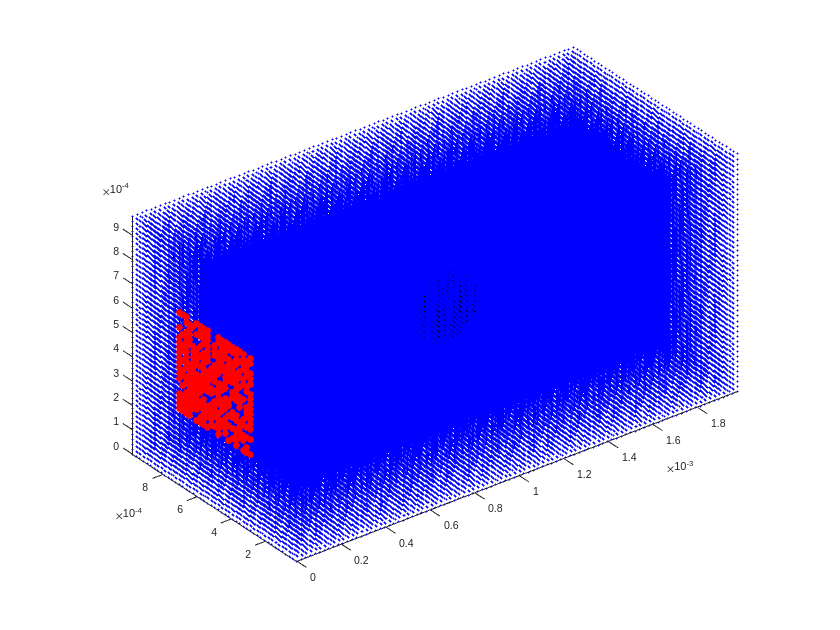

%% Data Preprocessing for Selected Particles
% -------------------------------------------------
% This part is a repetition of the content of example1. It generate the streamlines for particles 
% at the left. It requires 5 min and it can be skipped as it not used for stresses.
% note: the duration of the simulation enables the particles in the center (slowest part) to
% cross only half of the cell.

% Pick n particles randomly from the left inlet and included in the mask of the solid (initial frame)
n = 300;
tol = 0.5; % add 40% particles around
selectionbox = NaN(3,2);
selectionbox(iflow,:) = [X0.BOX(iflow,1), X0.BOX(iflow,1)+2*rbead];
selectionbox(iothers,:) =  (1+tol)*(solidbox(iothers,2)-solidbox(iothers,1))*[-1 1]/2 ...
    + (solidbox(iothers,1)+solidbox(iothers,2)) * [1 1]/2;
ok = true(nfluidatoms,1);
for c = 1:3
    ok = ok & (fluidxyz(:,c)>=selectionbox(c,1)) & (fluidxyz(:,c)<=selectionbox(c,2));
end
icandidates = find(ok);
iselected = icandidates(MDunidrnd(length(icandidates),n));
selectedid = fluidid(iselected); % ID to be used
% plot selected particles and other ones
figure, hold on
plot3D(fluidxyz,'b.')
plot3D(fluidxyz(iselected,:),'ro','markerfacecolor','r')
plot3D(solidxyz,'ks','markerfacecolor','k')
view(3), axis equal


% Generate the trajectory for the selected particles (for all frames)
% All data are loaded with Lamdumpread2() with a single call using 'usesplit'
% each split is loaded individually and only atoms matching selectedid are stored
% all atoms are sorted as selectedid (no need to sort them)
Xselection = lamdumpread2(fullfile(datafolder,dumpfile),'usesplit',[],timesteps,selectedid);

Use the prefetch (split: TIMESTEP 0) folder (instead of '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000000000.mat		27-Jul-2023 20:52:07		1.1 MBytes		../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
Use the prefetch (split: TIMESTEP 1000) folder (instead of '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000001000.mat		27-Jul-2023 20:52:09		6.3 MBytes		../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
Use the prefetch (split: TIMESTEP 2000) folder (instead of '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dum


% Collect the trajectory of the solid particle for all frames
Xsolid = lamdumpread2(fullfile(datafolder,dumpfile),'usesplit',[],timesteps,solidid);

Use the prefetch (split: TIMESTEP 0) folder (instead of '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000000000.mat		27-Jul-2023 20:52:07		1.1 MBytes		../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
Use the prefetch (split: TIMESTEP 1000) folder (instead of '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000001000.mat		27-Jul-2023 20:52:09		6.3 MBytes		../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
Use the prefetch (split: TIMESTEP 2000) folder (instead of '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dum

### 2.3 Main loop to collect trajectories


% Store the trajectories stored in a ntimesteps x 3 x n matrix
% missing data will
[seltraj,selveloc] = deal(NaN(ntimesteps,3,n,'single'));
solidtraj = NaN(ntimesteps,3,nsolidatoms,'double');
goodframes = true(ntimesteps,1);
for it = 1:ntimesteps
    % read fluid atoms
    selframe = Xselection.ATOMS(Xselection.ATOMS{:,'TIMESTEP'} == timesteps(it),:);
    nfoundatoms = size(selframe,1);
    if nfoundatoms<n % incomplete dumped frame (it may happen in LAMMPS)
        dispf('incomplete frame %d/%d (t=%0.4g): %d of %d fluid atoms missing',it,ntimesteps,timesteps(it),n-nfoundatoms,n)
        [~,iatoms,jatoms] = intersect(selectedid,selframe.id,'stable');
        seltraj(it,:,iatoms) = permute(selframe{jatoms,{'x','y','z'}},[3 2 1]);
        goodframes(it) = false;
    else
        seltraj(it,:,:) = permute(selframe{:,{'x','y','z'}},[3 2 1]);
        selveloc(it,:,:) = permute(selframe{:,{'vx','vy','vz'}},[3 2 1]);
    end
    % read solid atoms
    solidframe = Xsolid.ATOMS(Xsolid.ATOMS{:,'TIMESTEP'} == timesteps(it),:);
    nfoundatoms = size(solidframe,1);
    if nfoundatoms<nsolidatoms % incomplete dumped frame (it may happen in LAMMPS)
        dispf('incomplete frame %d/%d (t=%0.4g): %d of %d solid atoms missing',it,ntimesteps,timesteps(it),nsolidatoms-nfoundatoms,nsolidatoms)
        [~,iatoms,jatoms] = intersect(solidid,solidframe.id,'stable');
        solidtraj(it,:,iatoms) = permute(solidframe{jatoms,{'x','y','z'}},[3 2 1]);
        goodframes(it) = false;
    else
        solidtraj(it,:,:) = permute(solidframe{:,{'x','y','z'}},[3 2 1]);
    end
end
% velocity magnitude for the fluid particles
selveloc_magnitude = squeeze(sqrt(sum(selveloc.^2, 2)));


### 2.4 Trajectory visualization

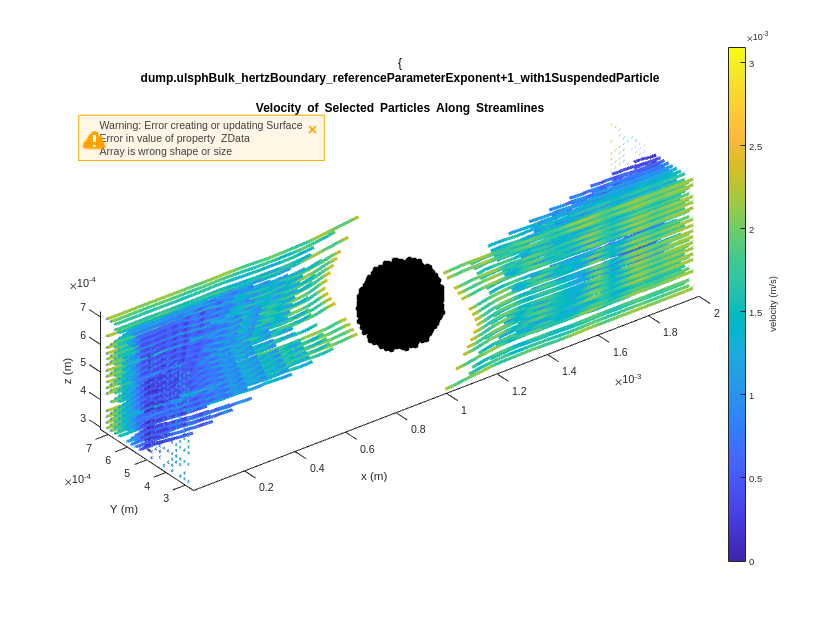

% Trajectory Visualization
% -------------------------------------------------
% streamlines with color representing velocity magnitude
figure, hold on
col = parula(n);
for i=1:n
    jumps = [1;ntimesteps+1];
    for d=1:3
        jumps = unique([jumps;find(abs(diff(seltraj(:,d,i)))>boxdims(d)/2)+1]);
    end
    for j=1:length(jumps)-1
        u = jumps(j):jumps(j+1)-1;
        streamline = seltraj(u, :, i);
        color_line3(streamline(:, 1), streamline(:, 2), streamline(:, 3), selveloc_magnitude(u, i), 'linewidth', 3);
        % faster method but without streamline
        %plot3(traj(u,1,i),traj(u,2,i),traj(u,3,i),'-','linewidth',3,'color',col(i,:))
    end
end
plot3D(solidxyz,'ko','markerfacecolor','k','markersize',5)
view(3), axis equal
title({'\rm{' strrep(dumpfile, '_', '\_') '}:' '\bf{Velocity of Selected Particles Along Streamlines}'}, 'Interpreter', 'tex')
xlabel('x (m)'), ylabel('Y (m)'), zlabel('z (m)')
hc = colorbar; hc.Label.String = 'velocity (m/s)';

## 3. Stress Analysis

This section is progressive and combine a broad variety of approaches with increasing refinements and sophistications


%% Stress Analysis in Reference Frame (PART 2)
% -------------------------------------------------
% This part focuses on evaluating the mechanical interactions and stress in a particular 
% frame. Specifically, we employ a late-stage frame (closer to steady-state conditions) to 
% derive insights into the types of contacts between fluid and solid atoms.
% 
% * `timestepforstress`: Time step selected for stress analysis.
% * `Xstress`: Data structure containing all relevant atomic information at the chosen time step.
% * `verletListCross`: A specialized Verlet list that segregates contacts based on atom types.
% * `isincontact`, `isincontactwithsolid`, `isincontactwithfluid`: Boolean fields that signify 
% whether an atom is in contact, and with which type of atom.
%
% Here we rely heavily on a short-cut-off Verlet list for efficiency, separating cross-terms
% and characterizing specific types of atomic interactions.
clear Xsolid Xmiddle X0 Xselection streamline 


### 3.1 Initialization and possibly loop on several frames

Use the prefetch (split: TIMESTEP 101000) folder (instead of '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000101000.mat		27-Jul-2023 20:58:47		7.7 MBytes		../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.29 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[1/9] TIMESTEP = 101000 (plot)


Build Verlet list by searching in blocks...
... done in 0.1869 s with 1584 search blocks | minimum distance 1.54e-05
	 Sort the Verlet list...
	 ... done in 0.647 s
buildVerletList: all done in 27.3 s for 313344 atoms


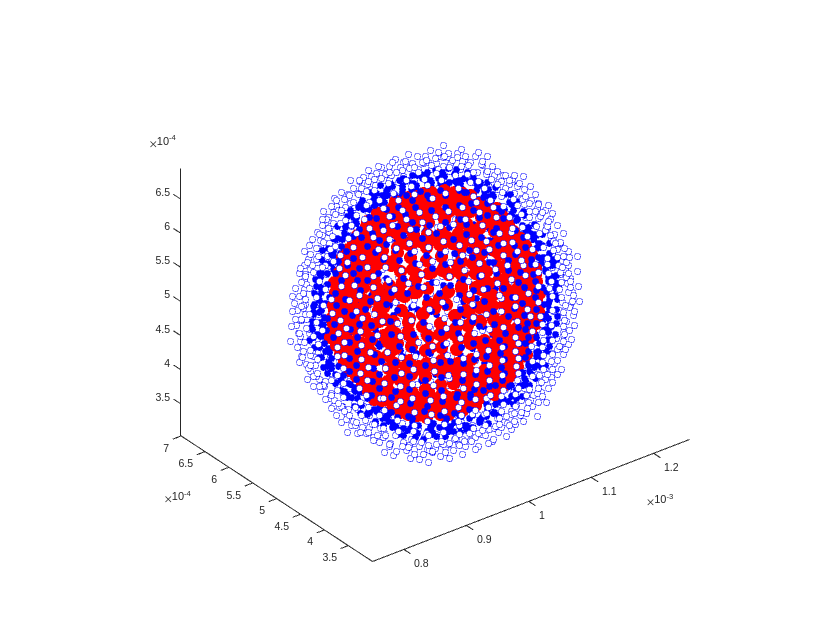

	number of fluid atoms in contact with solid 853


	number of solid atoms in contact with fluid 566 (neighbors 1094)


Use the prefetch (split: TIMESTEP 202000) folder (instead of '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000202000.mat		27-Jul-2023 21:03:44		8.1 MBytes		../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.277 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[2/9] TIMESTEP = 202000 (no plot)


Build Verlet list by searching in blocks...
... done in 0.1811 s with 1584 search blocks | minimum distance 1.506e-05
	 Sort the Verlet list...
	 ... done in 0.676 s
buildVerletList: all done in 28.4 s for 313344 atoms


Use the prefetch (split: TIMESTEP 304000) folder (instead of '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000304000.mat		27-Jul-2023 21:08:00		8.3 MBytes		../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.27 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[3/9] TIMESTEP = 304000 (no plot)


Build Verlet list by searching in blocks...
... done in 0.2024 s with 1584 search blocks | minimum distance 1.441e-05
	 Sort the Verlet list...
	 ... done in 0.666 s
buildVerletList: all done in 27.4 s for 313344 atoms


Use the prefetch (split: TIMESTEP 405000) folder (instead of '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000405000.mat		27-Jul-2023 21:12:42		8.4 MBytes		../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.269 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[4/9] TIMESTEP = 405000 (no plot)


Build Verlet list by searching in blocks...
... done in 0.1682 s with 1584 search blocks | minimum distance 1.37e-05
	 Sort the Verlet list...
	 ... done in 0.677 s
buildVerletList: all done in 27.9 s for 313344 atoms


Use the prefetch (split: TIMESTEP 506000) folder (instead of '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000506000.mat		27-Jul-2023 21:17:15		8.5 MBytes		../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.272 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[5/9] TIMESTEP = 506000 (no plot)


Build Verlet list by searching in blocks...
... done in 0.1637 s with 1584 search blocks | minimum distance 1.479e-05
	 Sort the Verlet list...
	 ... done in 0.674 s
buildVerletList: all done in 27.4 s for 313344 atoms


Use the prefetch (split: TIMESTEP 608000) folder (instead of '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000608000.mat		27-Jul-2023 21:21:52		8.6 MBytes		../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.271 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[6/9] TIMESTEP = 608000 (no plot)


Build Verlet list by searching in blocks...
... done in 0.2936 s with 1584 search blocks | minimum distance 1.476e-05
	 Sort the Verlet list...
	 ... done in 0.684 s
buildVerletList: all done in 27.5 s for 313344 atoms


Use the prefetch (split: TIMESTEP 709000) folder (instead of '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000709000.mat		27-Jul-2023 21:26:29		8.6 MBytes		../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.274 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[7/9] TIMESTEP = 709000 (no plot)


Build Verlet list by searching in blocks...
... done in 0.2175 s with 1584 search blocks | minimum distance 1.364e-05
	 Sort the Verlet list...
	 ... done in 0.687 s
buildVerletList: all done in 27.3 s for 313344 atoms


Use the prefetch (split: TIMESTEP 811000) folder (instead of '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000811000.mat		27-Jul-2023 21:31:05		8.7 MBytes		../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.275 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[8/9] TIMESTEP = 811000 (no plot)


Build Verlet list by searching in blocks...
... done in 0.05926 s with 1584 search blocks | minimum distance 1.456e-05
	 Sort the Verlet list...
	 ... done in 0.682 s
buildVerletList: all done in 27.3 s for 313344 atoms


Use the prefetch (split: TIMESTEP 912000) folder (instead of '../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle')...
	TIMESTEP_000912000.mat		27-Jul-2023 21:35:16		8.8 MBytes		../dumps/pub1/numericalViscosimeter_reference_ulsphBulk_hertzBoundary/PREFETCH_dump.ulsphBulk_hertzBoundary_referenceParameterExponent+1_with1SuspendedParticle
...loaded in 0.278 s



-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-*-
[9/9] TIMESTEP = 912000 (plot)


Build Verlet list by searching in blocks...
... done in 0.2728 s with 1584 search blocks | minimum distance 1.461e-05
	 Sort the Verlet list...
	 ... done in 0.689 s
buildVerletList: all done in 27.4 s for 313344 atoms


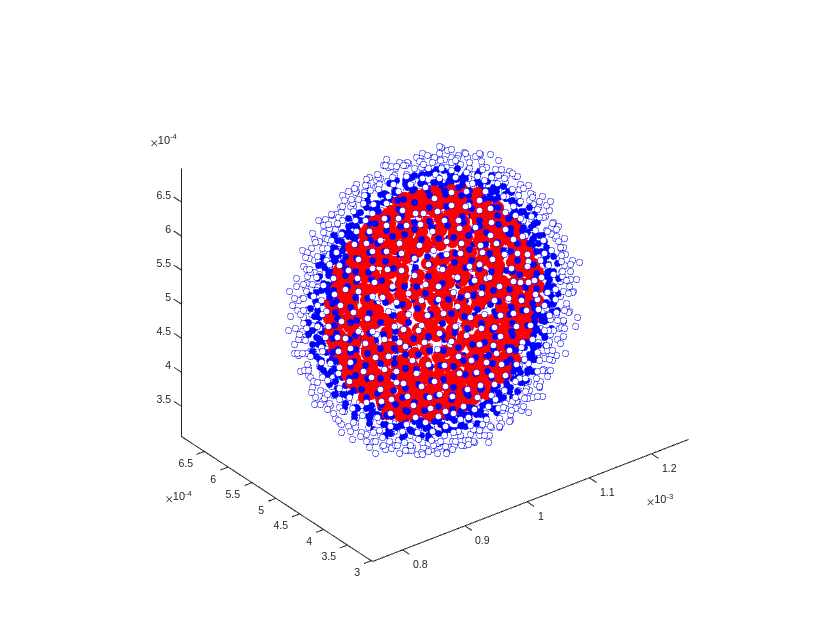

	number of fluid atoms in contact with solid 886


	number of solid atoms in contact with fluid 580 (neighbors 1035)


% General container for storing data for different timesteps
postdata = repmat(struct('type','Landshoff|Hertz','timestep',NaN,'Xfluid',[],'Xsolid',[],'force',[]),0,0);


% Extract the Specific Frame for Stress Interpretation
% Selects a time step that is presumably closer to the steady-state to perform stress analysis.
list_timestepforstess = unique(timesteps(ceil((0.1:0.1:0.9)*ntimesteps)));
nlist_timestepforstess = length(list_timestepforstess);
consideredtimesteps = 1:nlist_timestepforstess;

% === Loop on all selected time steps ===
altxt = {'no plot','plot'};


for i_timestepforstess = consideredtimesteps


    % current frame
    timestepforstress = list_timestepforstess(i_timestepforstess);
    Xstress = lamdumpread2(fullfile(datafolder,dumpfile),'usesplit',[],timestepforstress); % middle frame
    doplot = ismember(timestepforstress,list_timestepforstess([1 end]));
    dispf('\n%s-\n[%d/%d] TIMESTEP = %d (%s)',repmat('-*',1,40),i_timestepforstess,nlist_timestepforstess,timestepforstress,altxt{doplot+1})


    % Categorization of Atom Types
    % Identifies the most and least populous atom types to discern between fluid and solid types.
    T = Xstress.ATOMS.type;
    natomspertype = arrayfun(@(t) length(find(T==t)),atomtypes);
    [~,fluidtype] = max(natomspertype);
    [~,solidtype] = min(natomspertype);
    walltypes = setdiff(atomtypes,[fluidtype,solidtype]);

    % Boolean Classification of Atom Types
    Xstress.ATOMS.isfluid = Xstress.ATOMS.type==fluidtype;
    Xstress.ATOMS.issolid = Xstress.ATOMS.type==solidtype;

    % Verlet List Construction with Short Cutoff
    % Builds a Verlet list with a short cutoff distance, designed to identify only the closest neighbors.
    [verletList,cutoff,dmin,config,dist] = buildVerletList(Xstress.ATOMS,3*rbead);

    % Partition Verlet List Based on Atom Types
    % This Verlet list is partitioned based on atom types, distinguishing between interactions
    % that are exclusively fluid-fluid, solid-fluid, or solid-solid.
    verletListCross = partitionVerletList(verletList,Xstress.ATOMS);

    % Identify Contacting Atoms
    % The atoms that are in contact with each other are identified.
    Xstress.ATOMS.isincontact = ~cellfun(@isempty,verletListCross);
    Xstress.ATOMS.contacttypes = cellfun(@(v) Xstress.ATOMS.type(v)',verletListCross,'UniformOutput',false);

    % Identify Atoms in Contact with Solids and Fluids
    % Further filters the atoms in contact to identify which are in contact with solids and which with fluids.
    Xstress.ATOMS.isincontactwithsolid = cellfun(@(c) ismember(solidtype,c), Xstress.ATOMS.contacttypes);
    Xstress.ATOMS.isincontactwithfluid = cellfun(@(c) ismember(fluidtype,c), Xstress.ATOMS.contacttypes);

    % Flag Fluid Atoms in Contact with Solid and Vice Versa
    % Identifies fluid atoms that are in contact with solid atoms and solid atoms in contact with fluid atoms.
    Xstress.ATOMS.fluidincontactwithsolid = Xstress.ATOMS.isfluid & Xstress.ATOMS.isincontactwithsolid;
    Xstress.ATOMS.solidincontactwithfluid = Xstress.ATOMS.issolid & Xstress.ATOMS.isincontactwithfluid;

    % Identify Indices for Analysis
    % Indices of fluid and solid atoms that are in contact with each other.
    ifluidcontact = find(Xstress.ATOMS.fluidincontactwithsolid);
    isolidcontact = find(Xstress.ATOMS.solidincontactwithfluid);

    % Extend Fluid Atoms Set with Neighbors (Not Directly in Contact)
    % Extends the set of fluid atoms under consideration to include their closest neighbors.
    ifluidcontact_withneighbors = unique(union(ifluidcontact,cat(2,verletList{ifluidcontact}))); % include neighbors
    ifluidcontact_withneighbors = ifluidcontact_withneighbors(T(ifluidcontact_withneighbors)==fluidtype); % filter, keep only fluids
    [~,~,ind_withoutneighbors] = intersect(ifluidcontact,ifluidcontact_withneighbors,'stable');
    notneighboringcontacts = setdiff(ifluidcontact_withneighbors,ifluidcontact_withneighbors(ind_withoutneighbors));

    % Visualization for some frames
    % filled red: solid "atoms" in contact with the fluid
    % filled blue: fluid "atoms" in contact with the solid (crown/shell)
    % empty blue: fluid "atoms" neighbor of previous ones but not contact
    % empty blue are used to calculate Landshoff forces at the position of filled ones
    if doplot
        figure, hold on
        plot3D(Xstress.ATOMS{ifluidcontact,{'x','y','z'}},'bo','markerfacecolor','b')
        plot3D(Xstress.ATOMS{notneighboringcontacts,{'x','y','z'}},'bo','markerfacecolor','w')
        plot3D(Xstress.ATOMS{isolidcontact,{'x','y','z'}},'ro','markersize',12,'markerfacecolor','r')
        axis equal, view(3), drawnow
        dispf('\tnumber of fluid atoms in contact with solid %d', length(ifluidcontact))
        dispf('\tnumber of solid atoms in contact with fluid %d (neighbors %d)', length(isolidcontact),length(notneighboringcontacts))
    end
end

### 3.2. Projection of velocity field on a regular grid

The interpolation process of large systems requires to be performed with `interp3SPHVerlet() `with the help of a Verletlist. The search for neighbors can be done for beads but also for arbitrary nodes from a mesh. The interpolation can be applied to scalar and vectorial fields. Once velocities are propertly calculated, it is possible to derive streamlines.

With large grids, the calculations are very intensive and may require a lot of memory. Reduce the grid size if your experience memory errors.

3935 fluid atoms have be found in the cross section around the solid


Calculate the 1 x 341435 pair distances...
	 ... done in 1.09 s
Find atoms within cuttoff...
	 ... done in 2.32 s
Build the Verlet list...
Building the Verlet list [completed: 94.1% | elapsed: 16 s | remaining: 1.01 s]
	 ... done in 17.3 s [min=0, median=66, max=122]
	 Sort the Verlet list...
	 ... done in 1.61 s
buildVerletList: all done in 23.5 s for 341435 atoms


INTERP3SPHVERLET interpolates 337500 x 3 grid points with a Verlet list including from 0 to 122 neighbors...
...done in 38.96 s. INTERP3SPHVerlet completed the interpolation of 337500 points with 3935 kernels


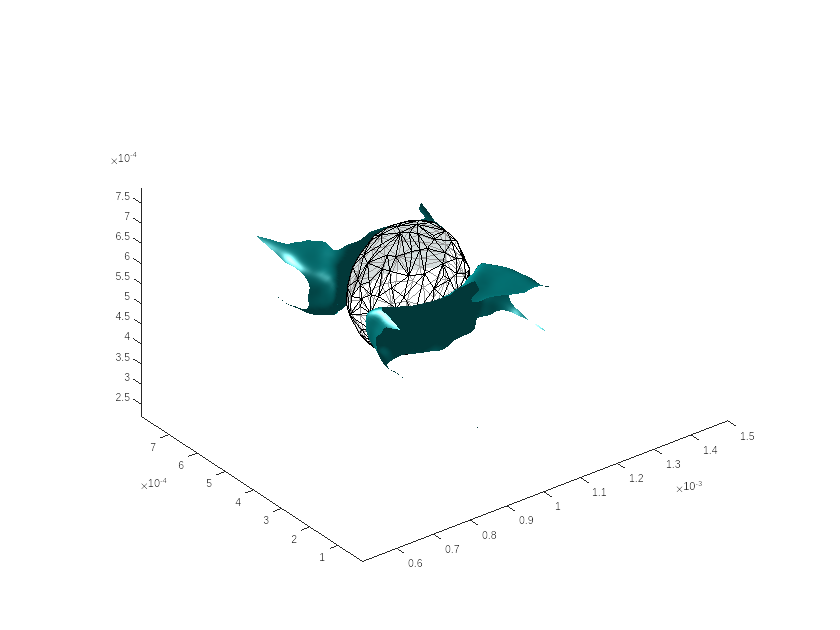

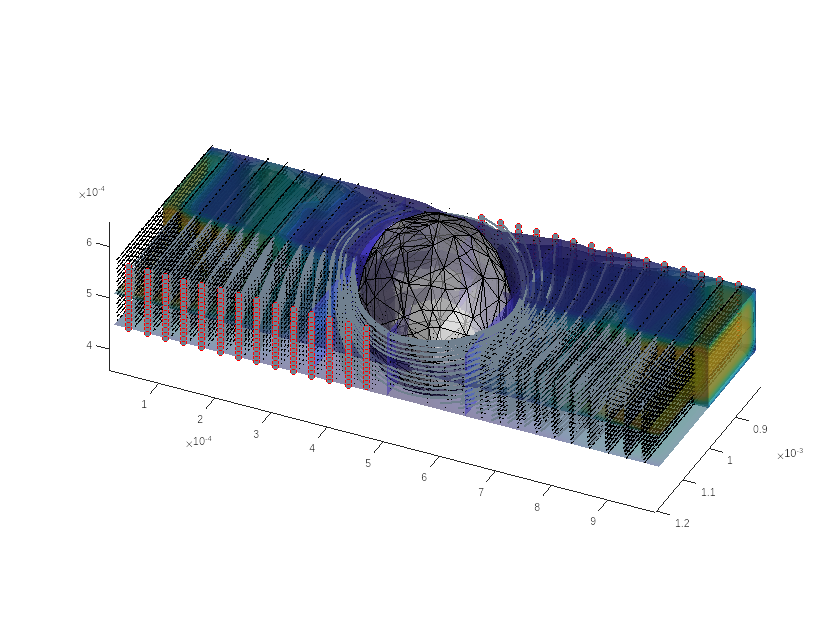

%% === 3D view of the fluid velocity around the solid ===
DOINTENSIVECALC = true; % set it to false, to prevent intensive calculations
% Definition of the Viewbox (for all grid-based visualizations)
coords = {'x','y','z'}; % Cartesian coordinates
vcoords = cellfun(@(c) ['v',c],coords,'UniformOutput',false); % vx, vy, vz
% Extract the box around solid atoms and include fluid ones
fluidbox = [ min(Xstress.ATOMS{Xstress.ATOMS.isfluid,coords})
    max(Xstress.ATOMS{Xstress.ATOMS.isfluid,coords}) ]';
solidbox = [ min(Xstress.ATOMS{Xstress.ATOMS.issolid,coords})
    max(Xstress.ATOMS{Xstress.ATOMS.issolid,coords}) ]';
[~,iflow] = max(max(Xstress.ATOMS{Xstress.ATOMS.isfluid,vcoords})); % direction of the flow
viewbox = fluidbox; viewbox(iflow,:) = solidbox(iflow,:);
if DOINTENSIVECALC % THIS SECTION IS VERY INTENSIVE (more than 5 mins)
    % 3D Cartesian Grid from the widow xw, yw, zw
    nresolution = [300 300 30]/2; % /2 for the notebook (removed in a real Matlab code)
    resolutionmax = max(nresolution);
    for icoord = 1:3
        viewbox(icoord,:) = mean(viewbox(icoord,:)) + [-1.2 1.2]*diff(viewbox(icoord,:))/2*nresolution(icoord)/resolutionmax;
        viewbox(icoord,1) = max(viewbox(icoord,1),fluidbox(icoord,1));
        viewbox(icoord,2) = min(viewbox(icoord,2),fluidbox(icoord,2));
    end
    hLandshoff = 5*rbead; %1.25e-5; % m
    xw = linspace(viewbox(1,1),viewbox(1,2),nresolution(1));
    yw = linspace(viewbox(2,1),viewbox(2,2),nresolution(2));
    zw = linspace(viewbox(3,1),viewbox(3,2),nresolution(3));
    insidewindow = Xstress.ATOMS.isfluid;
    for icoord = 1:3
        insidewindow = insidewindow ...
            & Xstress.ATOMS{:,coords{icoord}}>=viewbox(icoord,1) ...
            & Xstress.ATOMS{:,coords{icoord}}<=viewbox(icoord,2);
    end
    dispf('%d fluid atoms have be found in the cross section around the solid',length(find(insidewindow)));
    [Xw,Yw,Zw] = meshgrid(xw,yw,zw);
    XYZgrid = [Xw(:),Yw(:),Zw(:)];

    % Verlet Grid List: lists the beads close to a grid node/vertex
    XYZ = Xstress.ATOMS{insidewindow,coords}; % kernel centers
    VXYZ = buildVerletList({XYZgrid XYZ},1.2*hLandshoff); % special grid syntax

    % Interpolation of all velocity components (vx, vy, vz)
    % v3XYZgrid is the interpolated vectorial field
    % vxXYZgrid, vyXYZgrid, vzXYZgrid are the components
    % vXYZgrid is the magnitude
    % note: For interpolating the density only: interpolates ones(size(XYZ,1),1,'single')
    W = kernelSPH(hLandshoff,'lucy',3); % kernel expression
    vXYZ = Xstress.ATOMS{insidewindow,vcoords}; % kernel centers
    vXYZmag = sqrt(sum(vXYZ.^2,2)); % velocity magnitude
    mbead = 9.04e-12;
    Vbead = mbead/1000;
    v3XYZgrid = interp3SPHVerlet(XYZ,vXYZ,XYZgrid,VXYZ,W,Vbead);
    vxXYZgrid = reshape(v3XYZgrid(:,1),size(Xw)); vxXYZgrid(isnan(vxXYZgrid)) = 0;
    vyXYZgrid = reshape(v3XYZgrid(:,2),size(Xw)); vyXYZgrid(isnan(vyXYZgrid)) = 0;
    vzXYZgrid = reshape(v3XYZgrid(:,3),size(Xw)); vzXYZgrid(isnan(vzXYZgrid)) = 0;
    vXYZgrid  = reshape(sqrt(sum(v3XYZgrid.^2,2)),size(Xw));

    % 3D Figure (for control only, we plot one iso-velocity surface)
    % we add the solid phase as a meshed solid
    figure, hold on
    visocontour = max(vXYZmag)/10;
    isosurface(Xw,Yw,Zw,vXYZgrid,visocontour)
    DT = delaunayTriangulation(double(Xstress.ATOMS{isolidcontact,{'x','y','z'}}));
    K = convexHull(DT);
    trisurf(K, DT.Points(:,1), DT.Points(:,2), DT.Points(:,3), 'FaceColor', 'w','Edgecolor','k','FaceAlpha',0.6);
    lighting gouraud, camlight left, axis equal, view(3) % shading interp

    %% cuts and slices (caps are put on the smallest contour)
    figure, hold on
    vXYZcut = vXYZgrid;
    boxcenter = (fluidbox(:,1)+fluidbox(:,2))/2; % boxcenter = (solidbox(:,1)+solidbox(:,2))/2;
    [Xwcut,Ywcut,Zwcut] = deal(Xw,Yw,Zw);
    vXYZcut(:,yw>boxcenter(2),:) = [];
    Xwcut(:,yw>boxcenter(2),:) = [];
    Ywcut(:,yw>boxcenter(2),:) = [];
    Zwcut(:,yw>boxcenter(2),:) = [];
    % vXYZcut(:,:,zw>boxcenter(3),:) = [];
    % Xwcut(:,:,zw>boxcenter(3),:) = [];
    % Ywcut(:,:,zw>boxcenter(3),:) = [];
    % Zwcut(:,:,zw>boxcenter(3),:) = [];
    % iso-surface val
    colors = parula(256);
    visomax = max(vXYZmag);
    visocontour = visomax * [1/20,1/10,1/5, 1/4, 1/3, 1/2];
    visocolors = interp1(linspace(0,visomax,size(colors,1)),colors,visocontour);
    for icontour = 1:length(visocontour)
        patch(isosurface(Xwcut,Ywcut,Zwcut,vXYZcut, visocontour(icontour)),...
            'FaceColor',visocolors(icontour,:),'EdgeColor','none','FaceAlpha',0.6);
    end
    p2 = patch(isocaps(Xwcut,Ywcut,Zwcut,vXYZcut, visocontour(1)),'FaceColor','interp','EdgeColor','none','FaceAlpha',0.6);
    colormap(colors), camlight('right'), lighting gouraud, view(3), axis equal
    trisurf(K, DT.Points(:,1), DT.Points(:,2), DT.Points(:,3), 'FaceColor', 'w','Edgecolor','k','FaceAlpha',0.6);
    hs= slice(Xw,Yw,Zw,vXYZgrid,boxcenter(1), ...
        [solidbox(2,1) boxcenter(2) solidbox(2,2)], ...
        [viewbox(3,1) boxcenter(3)]);
    set(hs,'edgecolor','none','facealpha',0.5)
    view(115,34)
    % add quiver plot
    quiver3(Xw(1:5:end,1:5:end,1:1:end),Yw(1:5:end,1:5:end,1:1:end),Zw(1:5:end,1:5:end,1:1:end), ...
        vxXYZgrid(1:5:end,1:5:end,1:1:end),vyXYZgrid(1:5:end,1:5:end,1:1:end),vzXYZgrid(1:5:end,1:5:end,1:1:end), ...
        'color','k','LineWidth',1)
    % add streamlines (note that all arguments required to be double)
    [startX,startY,startZ] = meshgrid(double(xw(1)),double(yw(5:5:end-5)),double(zw(1:1:end)));
    vstart = interp3(Xw,Yw,Zw,vxXYZgrid,startX,startY,startZ); startX(vstart<0) = double(xw(end));
    hsl = streamline(double(Xw),double(Yw),double(Zw),vxXYZgrid,vyXYZgrid,vzXYZgrid,startX,startY,startZ);
    set(hsl,'linewidth',2,'color',[0.4375    0.5000    0.5625])
    plot3(startX(:),startY(:),startZ(:),'ro','markerfacecolor',[0.4375    0.5000    0.5625])
end

### 3.3 Landshoff forces

%% Landshoff forces in the fluid
%
% This section is dedicated to the calculation of Landshoff forces in the fluid medium.
% The computation is confined to a shell or "crown" around the solid particles.
% Here, we build a new Verlet list specific to the fluid particles around solid structures.
%
% * `Xfluidcontact_withneighbors`: Atomic information specifically for the fluid atoms in the vicinity of the solid.
% * `Vfluidcontact_withneighbors`: Verlet list constructed for these neighboring fluid atoms.
% * `Flandshoff`: Landshoff forces calculated based on the new Verlet list.
% * `f`: Magnitude of the Landshoff forces.
%
% Finally, visualization aids are employed to graphically represent these forces and their directions.


% Extract Information for Fluid Atoms in Contact with Neighbors
% Obtains the atomic information for fluid atoms in the vicinity of solid atoms, as identified earlier.
Xfluidcontact_withneighbors = Xstress.ATOMS(ifluidcontact_withneighbors,:);

% Verlet List Construction for Fluid Atoms
% Constructs a Verlet list for these neighboring fluid atoms with a larger cutoff (4*rbead).
Vfluidcontact_withneighbors = buildVerletList(Xfluidcontact_withneighbors,4*rbead);

Calculate the 1921 x 1921 pair distances...
	 ... done in 0.00487 s
Find atoms within cuttoff...
	 ... done in 0.00582 s
Build the Verlet list...
	 ... done in 0.0473 s [min=9, median=21, max=29]
	 Sort the Verlet list...
	 ... done in 0.00591 s
buildVerletList: all done in 0.0767 s for 1921 atoms



%%% Compute Landshoff Forces
% Computes Landshoff forces based on the new Verlet list.
% The config structure (configLandshoff) should match the input values of the simulation or equivalent
hLandshoff = 5*rbead; %1.25e-5; % m
configLandshoff = struct( ...
    'gradkernel', kernelSPH(hLandshoff,'lucyder',3),...kernel gradient
    'h', hLandshoff,...smoothing length (m)
    'c0',0.32,...speed of the sound (m/s)
    'q1',30,... viscosity coefficient (-)
    'rho', 1000, ...density
    'm', 9.04e-12 ...
    );
Flandshoff = forceLandshoff(Xfluidcontact_withneighbors,[],Vfluidcontact_withneighbors,configLandshoff);

Calculate Landshoff forces between [1921 x 3] atoms...
	 ... done in 0.0539 s


Flandshoff_all = Flandshoff;

% Restrict to the Crown/Shell Around the Solid
% Filters out the Landshoff forces, focusing only on the "crown" or shell around the solid atoms.
Flandshoff = double(Flandshoff(ind_withoutneighbors,:)); % we restrict only to the crown/shell
flandshoff = sqrt(sum(Flandshoff.^2,2));
statvec(flandshoff,'Landshoff',sprintf('<-- TIMESTEP: %d',timestepforstress))

Landshoff:  2.5%>       4.96 |  25.0%>      12.42 |  50.0%>      17.58 |  75.0%>       23.4 |  97.5%>      36.87 | 886 values | average = 18.463 <-- TIMESTEP: 912000



%%% Store the current result
postdata(end+1).type = 'Landshoff'; % end+1 triggers a new object
postdata(end).timestep = timestepforstress; % we fill it with end
postdata(end).Xfluid = Xstress.ATOMS(ifluidcontact,:);
postdata(end).Xsolid = Xstress.ATOMS(isolidcontact,:);
postdata(end).force = Flandshoff;

% loop here to accumulate more postdata

### 3.4 Hertz Contacts

%%% Compute Hertz contacts
% Extract Information for Fluid Atoms in Contact
Xcontactregion = Xstress.ATOMS(union(ifluidcontact,isolidcontact),:);
% Verlet List Construction for Solid Atoms (only) and considering only Fluid Atoms as neighbors
[Vcontactregion,~,dmincontact] = buildVerletList(Xcontactregion,3*rbead,[],[],[],Xcontactregion.isfluid,Xcontactregion.issolid);

Calculate the 1 x 1466 pair distances...
	 ... done in 0.00145 s
Find atoms within cuttoff...
	 ... done in 0.00146 s
Build the Verlet list...
	 ... done in 0.00554 s [min=0, median=0, max=11]
	 Sort the Verlet list...
	 ... done in 0.00477 s
buildVerletList: all done in 0.0268 s for 1466 atoms


% Compute Hertz Forces
Rfluid = 1.04e-5; % m
Rsolid = 1.56e-5; % m
Rfluid = Rsolid;
configHertz = struct('R',{Rsolid Rfluid},'E',2000);
FHertz = forceHertz(Xcontactregion,Vcontactregion,configHertz);
fhertz = sqrt(sum(FHertz.^2,2));
fhertzcontacts = fhertz(fhertz>0);
statvec(fhertzcontacts,'Hertz',sprintf('<-- TIMESTEP: %d\n\tsubjected to Rsolid=[%0.4g %0.4g] dmin/2=%0.4g',timestepforstress,configHertz(1).R,configHertz(2).R,dmincontact/2))

Hertz:  2.5%>  1.667e-08 |  25.0%>  4.027e-08 |  50.0%>  6.772e-08 |  75.0%>  8.849e-08 |  97.5%>   1.05e-07 | 580 values | average = 6.378e-08 <-- TIMESTEP: 912000
	subjected to Rsolid=[1.56e-05 1.56e-05] dmin/2=1.376e-05



%%% Store current results
% Store the current result
postdata(end+1).type = 'Hertz'; % end+1 triggers a new object
postdata(end).timestep = timestepforstress; % we fill it with end
postdata(end).Xfluid = [];
postdata(end).Xsolid = Xcontactregion(fhertz>0,:);
postdata(end).force = FHertz(fhertz>0);

% loop here to accumulate more postdata



## 4. Force Visualization

### 4.1 Solid visualization using a convex-hull

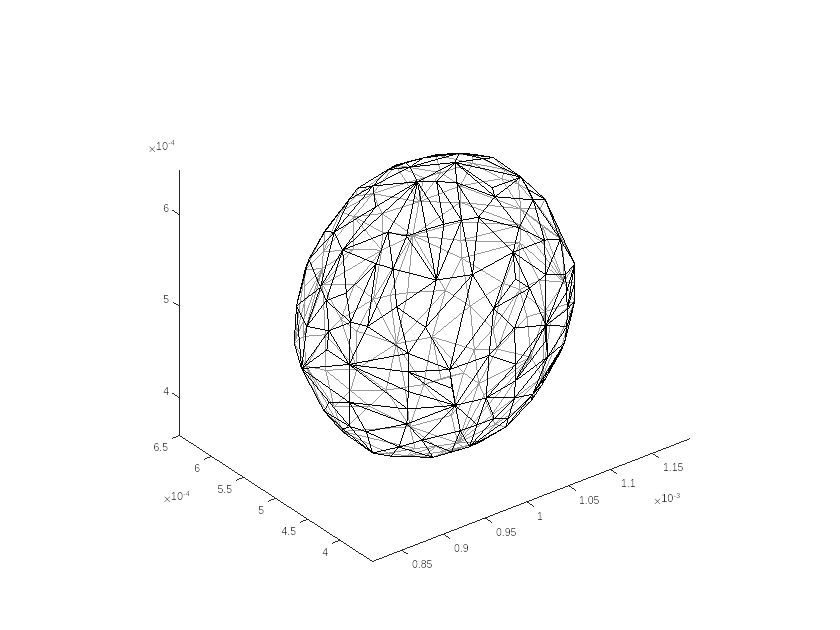

%% Visualization (bead-based) of Landshoff forces
% Creates a 3D visualization featuring both the solid structure and the fluid atoms under consideration.
% The Landshoff forces are represented as arrows originating from the fluid atoms.

% Tesselated Solid Visualization
% Utilizes Delaunay triangulation to represent the solid structure.
DT = delaunayTriangulation(double(Xstress.ATOMS{isolidcontact,{'x','y','z'}}));
K = convexHull(DT);
figure, hold on
trisurf(K, DT.Points(:,1), DT.Points(:,2), DT.Points(:,3), 'FaceColor', 'w','Edgecolor','k','FaceAlpha',0.6);
axis equal; view(3)

### 4.2. Basic visualization of Landshoff forces

%% Basic Visualization of Fluid Atoms and Landshoff Forces
% Landshoff forces are scaled and then visualized as arrows.
% fluid around
% scatter3D(Xfluidcontact_withneighbors{ind_withoutneighbors,{'x','y','z'}},f);
fmedian = median(flandshoff);
fmin = fmedian/50;
fscale = 4*rbead/fmedian;
start = Xfluidcontact_withneighbors{ind_withoutneighbors,{'x','y','z'}};
stop = start + Flandshoff * fscale;
start(flandshoff<fmin,:) = []; % non-significant forces are removed
stop(flandshoff<fmin,:) = [];
ha = arrow(start,stop,'length',4,'BaseAngle',60,'color','r');

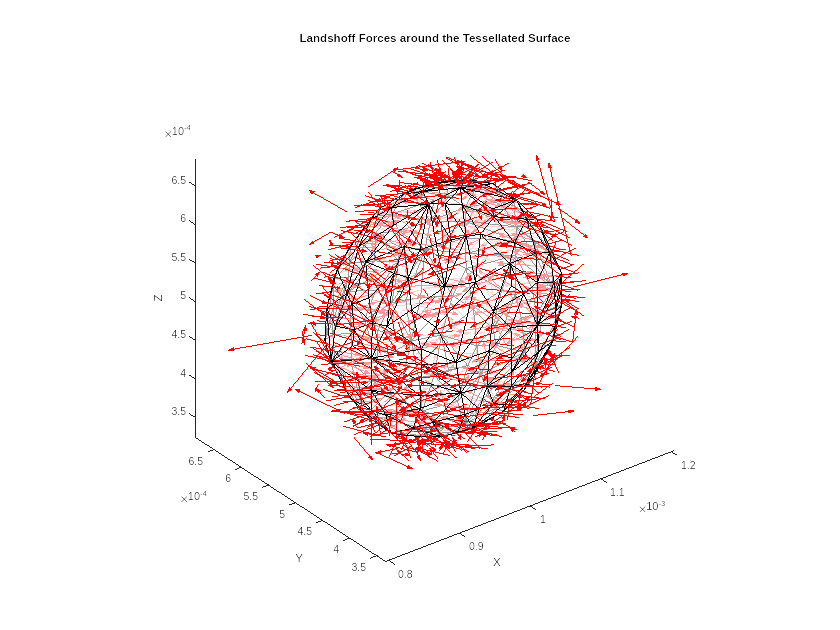

axis equal, view(3)
title('Landshoff Forces around the Tessellated Surface');
xlabel('X'); ylabel('Y'); zlabel('Z')

### 4.3. Advanced grid visualization of Lanshoff forces

The followed approach generalize the quiver plot used for the velocity field

%% Advanced LandShoff Visualization based on Grid Interpolation
coords = {'x','y','z'};
landshofbox = [ min(Xfluidcontact_withneighbors{:,coords})
                max(Xfluidcontact_withneighbors{:,coords}) ]';
xlw = linspace(viewbox(1,1),viewbox(1,2),50);
ylw = linspace(viewbox(2,1),viewbox(2,2),50);
zlw = linspace(viewbox(3,1),viewbox(3,2),50);
[Xlw,Ylw,Zlw] = meshgrid(xlw,ylw,zlw);
XYZlgrid = [Xlw(:),Ylw(:),Zlw(:)];
XYZl = Xfluidcontact_withneighbors{:,coords}; % kernel centers
% Interpolation at Grid Points of Flandshoff_all
VXYZl = buildVerletList({XYZlgrid XYZl},1.2*hLandshoff); % special grid syntax

Calculate the 1 x 126921 pair distances...
	 ... done in 0.222 s
Find atoms within cuttoff...
	 ... done in 0.396 s
Build the Verlet list...
	 ... done in 1.44 s [min=0, median=0, max=68]
	 Sort the Verlet list...
	 ... done in 0.286 s
buildVerletList: all done in 2.67 s for 126921 atoms


W = kernelSPH(hLandshoff,'lucy',3); % kernel expression
mbead = 9.04e-12;
Vbead = mbead/1000;
FXYZgrid = interp3SPHVerlet(XYZl,Flandshoff_all,XYZlgrid,VXYZl,W,Vbead);

INTERP3SPHVERLET interpolates 125000 x 3 grid points with a Verlet list including from 0 to 68 neighbors...
...done in 4.137 s. INTERP3SPHVerlet completed the interpolation of 125000 points with 1921 kernels


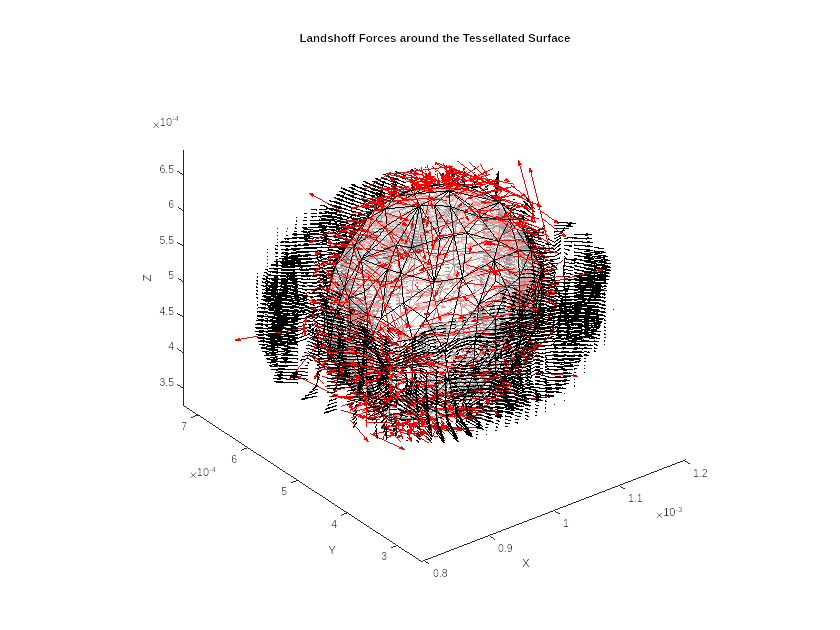

FXYZgridx = reshape(FXYZgrid(:,1),size(Xlw));
FXYZgridy = reshape(FXYZgrid(:,2),size(Ylw));
FXYZgridz = reshape(FXYZgrid(:,3),size(Zlw));
% Quiver plot to show the forces with an adjusted step
quiver3(...
    Xlw(1:2:end,1:2:end,1:2:end), ...
    Ylw(1:2:end,1:2:end,1:2:end), ...
    Zlw(1:2:end,1:2:end,1:2:end), ...
    FXYZgridx(1:2:end,1:2:end,1:2:end), ...
    FXYZgridy(1:2:end,1:2:end,1:2:end), ...
    FXYZgridz(1:2:end,1:2:end,1:2:end), ...
    'color','k','LineWidth',1)

### 4.4 Basic visualization of Hertz contacts

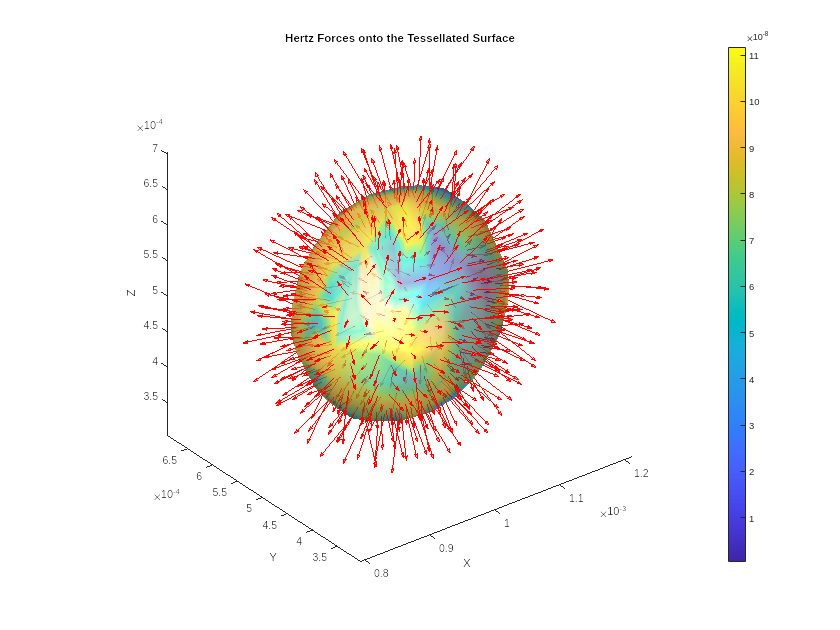

% Similar Visualization for Hertz Contacts
warning off
figure, hold on
fmedian = median(fhertzcontacts);
fmin = fmedian/50;
fscale = 4*rbead/fmedian;
start = Xcontactregion{fhertz>0,{'x','y','z'}};
stop = start - FHertz(fhertz>0,:) * fscale; % outwards forces (preferred)
start(fhertzcontacts<fmin,:) = []; % non-significant forces are removed
stop(fhertzcontacts<fmin,:) = [];
D = pdist2(DT.Points, start); % Compute pairwise distance
[~, idx] = min(D, [], 2); % Find closest particles on the mesh
trisurf(K, DT.Points(:,1), DT.Points(:,2), DT.Points(:,3), fhertzcontacts(idx),'Edgecolor','k','FaceAlpha',0.6);
axis equal; view(3), camlight('headlight'); camlight('left'); lighting phong; colorbar;
shading interp
ha = arrow(start,stop,'length',4,'BaseAngle',60,'color','r');
axis equal, view(3)
title('Hertz Forces onto the Tessellated Surface');
xlabel('X'); ylabel('Y'); zlabel('Z')

### 4.5 Advanced visualization of Hert contacts

The forces are calculated at the surface of the solid particle defined by a refined and smoothed mesh.

%% Grid Visualization of Hertz Contacts
% === STEP 1/5 === Original Delaunay triangulation and the convex hull
DT = delaunayTriangulation(double(Xstress.ATOMS{isolidcontact, {'x', 'y', 'z'}}));
K = convexHull(DT);
% === STEP 2/5 === refine the initial mesh by adding midpoints
% Extract the convex hull points and faces
hullPoints = DT.Points;
hullFaces = DT.ConnectivityList(K, :);
% Initialize a set to keep track of midpoints to ensure they are unique
midpointSet = zeros(0, 3);
% Calculate midpoints for each edge in each triangle and add to the point list
for faceIdx = 1:size(hullFaces, 1)
    face = hullFaces(faceIdx, :);
    for i = 1:3
        for j = i+1:3
            p1 = hullPoints(face(i), :);
            p2 = hullPoints(face(j), :);
            midpoint = (p1 + p2) / 2;        
            % Store the midpoint if unique
            if isempty(midpointSet) || ~ismember(midpoint, midpointSet, 'rows')
                midpointSet = [midpointSet; midpoint]; %#ok<AGROW>
            end
        end
    end
end
% Merge the original points and the new midpoints
newPoints = [hullPoints; midpointSet];
% Re-calculate the Delaunay triangulation and convex hull)
newDT = delaunayTriangulation(newPoints);
newK = convexHull(newDT);
% === STEP 3/5 ===  Laplacian Smoothing
points = newDT.Points;         % === Extract points and faces
faces = newDT.ConnectivityList(newK, :);
n = size(points, 1);           % === Initialize new points
newPoints = zeros(size(points)); 
neighbors = cell(n, 1);        % List of neighbors
for faceIdx = 1:size(faces, 1) % === Find the neighbors of each vertex
    face = faces(faceIdx, :);
    for i = 1:3
        vertex = face(i);
        vertex_neighbors = face(face ~= vertex);
        neighbors{vertex} = unique([neighbors{vertex}; vertex_neighbors(:)]);
    end
end
for i = 1:n                   % === Laplacian smoothing
    neighbor_indices = neighbors{i};
    if isempty(neighbor_indices) % Keep the point as is if it has no neighbors
        newPoints(i, :) = points(i, :); 
    else % Move the point to the centroid of its neighbors
        newPoints(i, :) = mean(points(neighbor_indices, :), 1);
    end
end
% Update the Delaunay triangulation with the smoothed points
newDT = delaunayTriangulation(newPoints);
newK = convexHull(newDT);
% === STEP 4/5 === Interpolate the Hertz forces on the triangular mesh
coords = {'x','y','z'};
XYZhtri = newDT.Points;
XYZh = Xcontactregion{:,coords}; % kernel centers
VXYZh = buildVerletList({XYZhtri XYZh},1.2*hLandshoff); % special grid syntax

Calculate the 1 x 2547 pair distances...
	 ... done in 0.00249 s
Find atoms within cuttoff...
	 ... done in 0.00441 s
Build the Verlet list...
	 ... done in 0.0479 s [min=0, median=0, max=70]
	 Sort the Verlet list...
	 ... done in 0.00787 s
buildVerletList: all done in 0.0738 s for 2547 atoms


W = kernelSPH(hLandshoff,'lucy',3); % kernel expression
mbead = 9.04e-12;
Vbead = mbead/1000;
FXYZtri = interp3SPHVerlet(XYZh,FHertz,XYZhtri,VXYZh,W,Vbead);

INTERP3SPHVERLET interpolates 1081 x 3 grid points with a Verlet list including from 0 to 70 neighbors...
...done in 0.1381 s. INTERP3SPHVerlet completed the interpolation of 1081 points with 1466 kernels


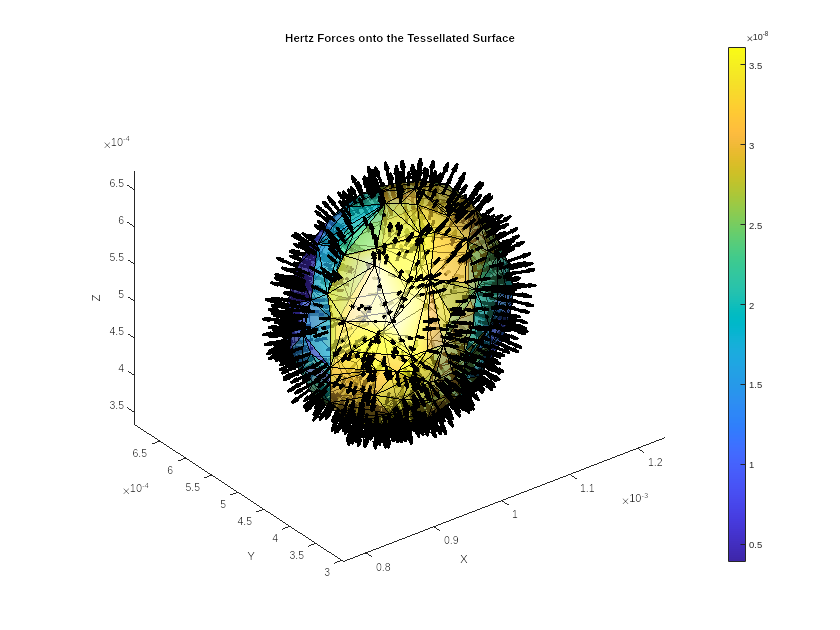

FXYZtrix = reshape(FXYZgrid(:,1),size(Xlw));
FXYZtriy = reshape(FXYZgrid(:,2),size(Ylw));
FXYZtriz = reshape(FXYZgrid(:,3),size(Zlw));
% === STEP 5/5 === Extract tagential forces
% Calculate face normals and centroids
points = newDT.Points;
faces = newK;
v1 = points(faces(:, 1), :) - points(faces(:, 2), :);
v2 = points(faces(:, 1), :) - points(faces(:, 3), :);
faceNormals = cross(v1, v2, 2);
faceNormals = faceNormals ./ sqrt(sum(faceNormals.^2, 2));
centroids = mean(reshape(points(faces, :), size(faces, 1), 3, 3), 3);
% Interpolate force at each centroid using scatteredInterpolant for each component
FInterp_x = scatteredInterpolant(XYZhtri, double(FXYZtri(:,1)), 'linear', 'nearest');
FInterp_y = scatteredInterpolant(XYZhtri, double(FXYZtri(:,2)), 'linear', 'nearest');
FInterp_z = scatteredInterpolant(XYZhtri, double(FXYZtri(:,3)), 'linear', 'nearest');
FXYZtri_at_centroids = [FInterp_x(centroids), FInterp_y(centroids), FInterp_z(centroids)];
% Calculate normal and tangential components of the force at each face centroid
normalComponent = dot(FXYZtri_at_centroids, faceNormals, 2);
normalForce = repmat(normalComponent, 1, 3) .* faceNormals;
tangentialForce = FXYZtri_at_centroids - normalForce;
% Calculate the magnitude of the tangential force
tangentialMagnitude = sqrt(sum(tangentialForce.^2, 2));


% === FINAL PLOTS ===
figure, hold on
trisurfHandle = trisurf(newK, newDT.Points(:, 1), newDT.Points(:, 2), newDT.Points(:, 3), 'Edgecolor', 'k', 'FaceAlpha', 0.6);
set(trisurfHandle, 'FaceVertexCData', tangentialMagnitude, 'FaceColor', 'flat');
colorbar;
% Quiver plot to show the forces with an adjusted step
quiver3(...
    XYZhtri(:,1), ...
    XYZhtri(:,2), ...
    XYZhtri(:,3), ...
    -FXYZtri(:,1), ...
    -FXYZtri(:,2), ...
    -FXYZtri(:,3), ...
    2, ...scale
    'color','k','LineWidth',3)
axis equal; view(3), camlight('headlight'); camlight('left'); lighting phong; colorbar;
title('Hertz Forces onto the Tessellated Surface');
xlabel('X'); ylabel('Y'); zlabel('Z')

## 5. Stress calculation and visualization

The difference between force and stress visualization is that you need to divide force by the surface area, where the force applies.

The current version use of example2 demonstrate the strategy without combining the method with the most advanced interpolation of forces on structured or unstructured mesh. For production, it is recommended to use forces which have be smoothed (interpolated) over a grid.

### 5.1 Template strategy

In the absence of grid, the results are not as smooth.

%% Project Landshoff Forces onto the Tessellated Surface
% Allocate space for the projected forces.
FprojectedN = zeros(size(Flandshoff));
FprojectedT = zeros(size(Flandshoff));
% Extract vertex coordinates from Delaunay Triangulation object.
vertices = DT.Points;
% Loop through all fluid atoms in contact with the solid.
for i = 1:length(ind_withoutneighbors)
    % Get the position of the current fluid atom.
    fluidPos = Xfluidcontact_withneighbors{ind_withoutneighbors(i),{'x','y','z'}};
    % Find the closest vertex on the tessellated surface.
    dists = sum((vertices - fluidPos).^2, 2);
    [~, closestVertexIdx] = min(dists);
    closestVertex = vertices(closestVertexIdx, :);
    % Calculate the vector from the fluid atom to the closest surface vertex.
    surfaceToFluidVec = fluidPos - closestVertex;
    % Normalize the vector.
    surfaceToFluidVec = surfaceToFluidVec / norm(surfaceToFluidVec);
    % Get the Landshoff force acting on the fluid atom.
    landshoffForce = Flandshoff(i, :);
    % Project the Landshoff force onto the normal.
    % Here, surfaceToFluidVec serves as the approximation of the outward normal at the closest vertex.
    projectedForceN = dot(landshoffForce, surfaceToFluidVec) * surfaceToFluidVec;
    % Store the projected force.
    FprojectedN(i, :) = projectedForceN;
    FprojectedT(i, :) = landshoffForce-projectedForceN;
end

% At this point, Fprojected contains the Landshoff forces projected onto the surface normal.
% Interpolation and Stress Magnitude Visualization
% Get faces and vertices from the tessellation.
faces = K; % Faces are given by the convex hull indices
vertices = DT.Points; % Vertex coordinates

% Loop over all faces to interpolate force and stress.
% Compute Barycentric Interpolation of Forces
% Initialize an array to store the interpolated forces and stresses
FNinterp_face = zeros(size(faces, 1), 3);
FTinterp_face = zeros(size(faces, 1), 3);
SNinterp_face = zeros(size(faces, 1), 3); % Normal stress per unit area
STinterp_face = zeros(size(faces, 1), 3); % Tangential stress per unit area


#### 5.1.1 Stress at faces

% Loop over all faces.
for i = 1:size(faces, 1)
    % Vertices of the triangle.
    vertex_indices = faces(i, :);
    A = vertices(vertex_indices(1), :);
    B = vertices(vertex_indices(2), :);
    C = vertices(vertex_indices(3), :);
    % Surface area of the triangle using Heron's formula.
    AB = norm(A - B);
    AC = norm(A - C);
    BC = norm(B - C);
    s = (AB + AC + BC) / 2;
    area_triangle = sqrt(s * (s - AB) * (s - AC) * (s - BC));
    % Normal to faces
    N = cross(B - A, C - A);
    N = N / norm(N); % Normalizing the normal vector
    % Forces at the vertices.
    F_A = FprojectedN(vertex_indices(1), :) + FprojectedT(vertex_indices(1), :);
    F_B = FprojectedN(vertex_indices(2), :) + FprojectedT(vertex_indices(2), :);
    F_C = FprojectedN(vertex_indices(3), :) + FprojectedT(vertex_indices(3), :);
    % The centroid (P) of the triangle for interpolation.
    P = (A + B + C) / 3;
    % Barycentric weights.
    ABC_inv = inv([A; B; C]);
    w = ABC_inv * P';
    % Interpolate the force at the centroid.
    Finterp = w(1) * F_A + w(2) * F_B + w(3) * F_C; 
    % Decompose the force into normal and tangential components
    F_N = dot(Finterp, N) * N; % only the normal force is trivial to compute
    F_T = Finterp - F_N; % by subtraction we get the tangential
    % Store interpolated force.
    Finterp_face(i, :) = Finterp;
    % Compute normal and tangential stress per unit area (Force/Area)
    SNinterp_face(i, :) = F_N / area_triangle;
    STinterp_face(i, :) = F_T / area_triangle;
end
% Compute the magnitude of interpolated stress.
face_force_magnitude = sqrt(sum(Finterp_face.^2, 2));
face_stressN_magnitude = sqrt(sum(SNinterp_face.^2, 2));
face_stressT_magnitude = sqrt(sum(STinterp_face.^2, 2));



#### 5.1.2. STress at vertices

% Add the smoothed force at vertices
% In computational geometry, the "valence" of a vertex refers to the number of edges
% (or equivalently, faces for a triangular mesh) incident to it. Valence can serve as
% an important metric in mesh quality and adaptivity considerations. 
% In our case, the valence is expected high (up to 11,12 faces per vertex), then poor mesh
uniq_vertex_indices = unique(faces(:)); % Find unique vertices used in faces
uniq_vertices = vertices(uniq_vertex_indices, :); % Create a new vertices array based on these unique indices
mapping = NaN(size(vertices, 1), 1); % Create a mapping from old vertex indices to new ones
mapping(uniq_vertex_indices) = 1:length(uniq_vertex_indices);
uniq_faces = mapping(faces); % Update the faces array to reflect new vertex indices
% Initialize interpolated forces at vertices
Finterp_vertex = zeros(size(uniq_vertices, 1), 3);
SNinterp_vertex = zeros(size(uniq_vertices, 1), 3);
STinterp_vertex = zeros(size(uniq_vertices, 1), 3);
% Create a mapping from vertices to faces
vertex_to_faces = cell(size(uniq_vertices, 1), 1);
for i = 1:size(uniq_faces, 1)
    for j = 1:3 % for each Vertex
        vertex_to_faces{uniq_faces(i, j)} = [vertex_to_faces{uniq_faces(i, j)}; i]; % we add the ith face
    end
end
% Interpolate forces at each vertex
for i = 1:size(uniq_vertices, 1)
    adjacent_faces = vertex_to_faces{i};
    if ~isempty(adjacent_faces)
        Finterp_vertex(i, :) = mean(Finterp_face(adjacent_faces, :), 1);
        SNinterp_vertex(i, :) = mean(SNinterp_face(adjacent_faces, :), 1);
        STinterp_vertex(i, :) = mean(STinterp_face(adjacent_faces, :), 1);
    end
end
vertex_force_magnitude = sqrt(sum(Finterp_vertex.^2, 2));
vertex_stressN_magnitude = sqrt(sum(SNinterp_vertex.^2, 2));
vertex_stressT_magnitude = sqrt(sum(STinterp_vertex.^2, 2));


### 5.2. Visualization

#### 5.2.1. Face-based visualization

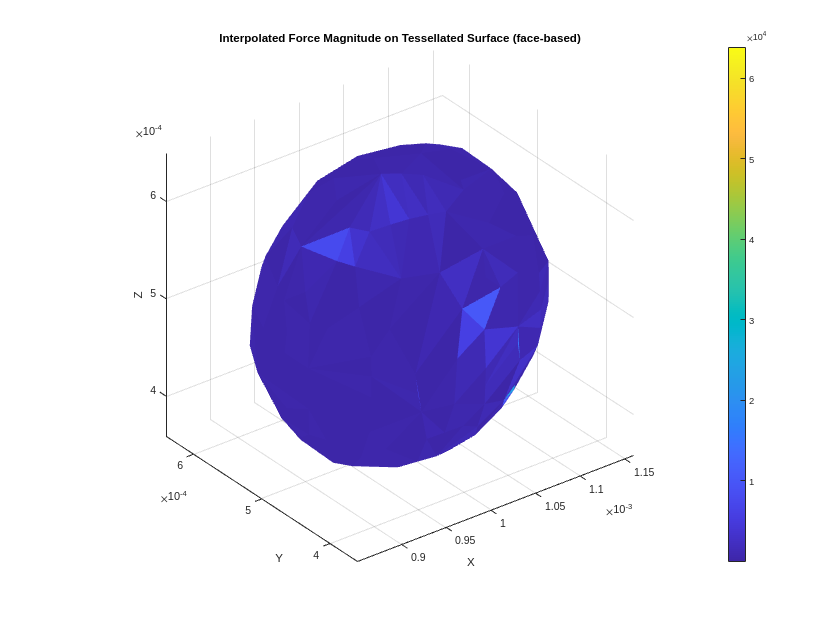

% Visualization (face-based, less smooth)
figure;
trisurf(faces, vertices(:, 1), vertices(:, 2), vertices(:, 3), face_force_magnitude, 'EdgeColor', 'none');
axis equal; view(3);
colorbar;
title('Interpolated Force Magnitude on Tessellated Surface (face-based)');
xlabel('X'); ylabel('Y'); zlabel('Z')

#### 5.2.2. Vertex-based visualization

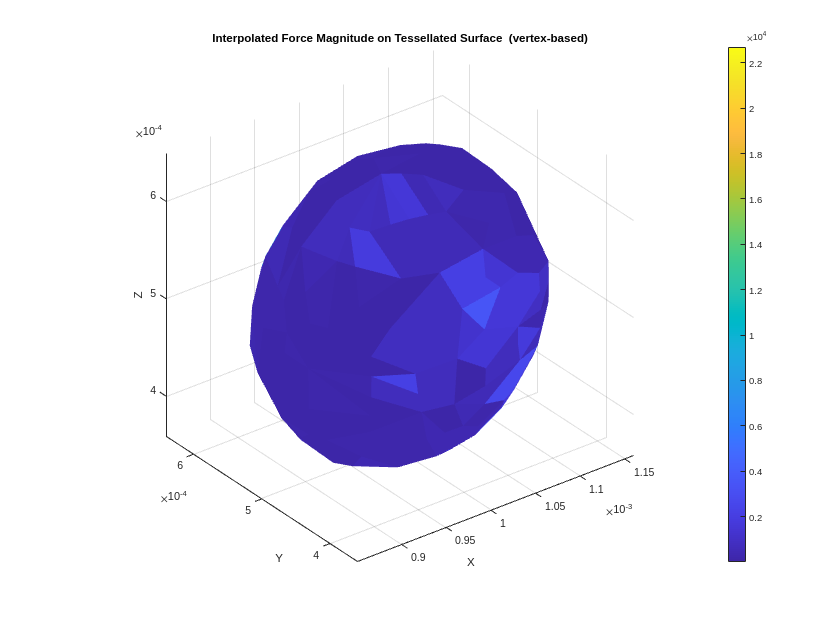

% Visualization (vertex-based, more smooth)
figure;
trisurf(uniq_faces, uniq_vertices(:, 1), uniq_vertices(:, 2), uniq_vertices(:, 3), vertex_force_magnitude, 'EdgeColor', 'none');
axis equal; view(3);
colorbar;
title('Interpolated Force Magnitude on Tessellated Surface  (vertex-based)');
xlabel('X'); ylabel('Y'); zlabel('Z')

#### 5.2.3 Slighly optimized visualization

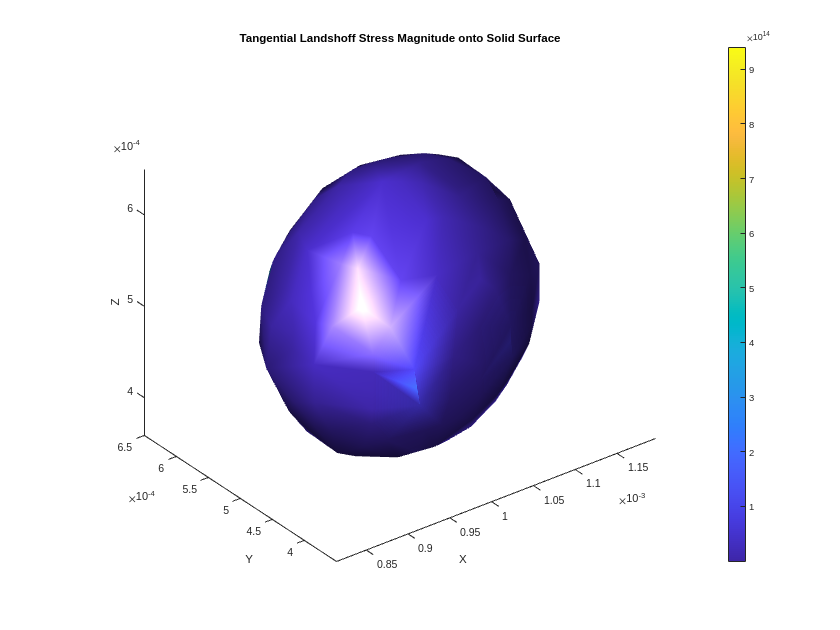

% Optimized visualization using 'patch' for stresses
% only vertex_stressT_magnitude is meaningful
figure;
patch_data.Vertices = uniq_vertices; % Prepare data for 'patch' function
patch_data.Faces = uniq_faces;
patch_data.FaceVertexCData = vertex_stressT_magnitude;
patch_data.FaceColor = 'interp';
patch_data.EdgeColor = 'none';
% Calculate vertex normals for smooth shading
patch_data.VertexNormals = -vertexNormal(triangulation(uniq_faces, uniq_vertices));
% Create the surface plot
p = patch(patch_data);
% Set view and lighting
axis equal;
view(3); camlight('headlight'); camlight('left'); lighting phong; colorbar;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Tangential Landshoff Stress Magnitude onto Solid Surface');

% Option to remove grid for a cleaner look
% grid off;
